拉格朗日中值定理：

例1：求 fx = 1/x^4 在 [1, 2]上的拉格朗日函数。

           f = f'(x) - (f(2) - f(1)) / (2 - 1)

syms x
df = diff(1/x^4)

$$df = -\frac{4}{x^{5}}$$

f = inline('-4/x^5-1/16+1'); % 建立函数
c = fzero(f, [1, 2])  % 求零点

c = 1.3367

    g = (f(2)-f(1))*x + b   

    g[1.3367] = f[1.3367] = 0.3132

        0.3132 = -0.9375*1.3367 + b

                 b =  1.5564

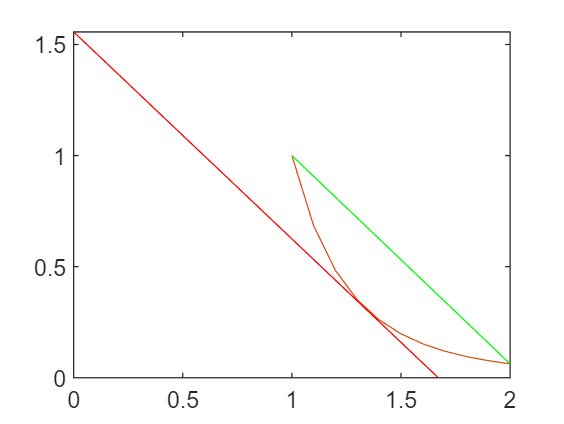

g = -0.9375*x + 1.5664;
u = 1:0.1:2;
z = 1./ u.^4;
plot(u, z);
hold on;
plot([0, 1.6708], [1.5564, 0], 'r');
syms x
f = 1/x^4;
x = 1;
y1 = eval(f);
x = 2;
y2 = eval(f);
plot([1,2], [y1, y2], 'g');

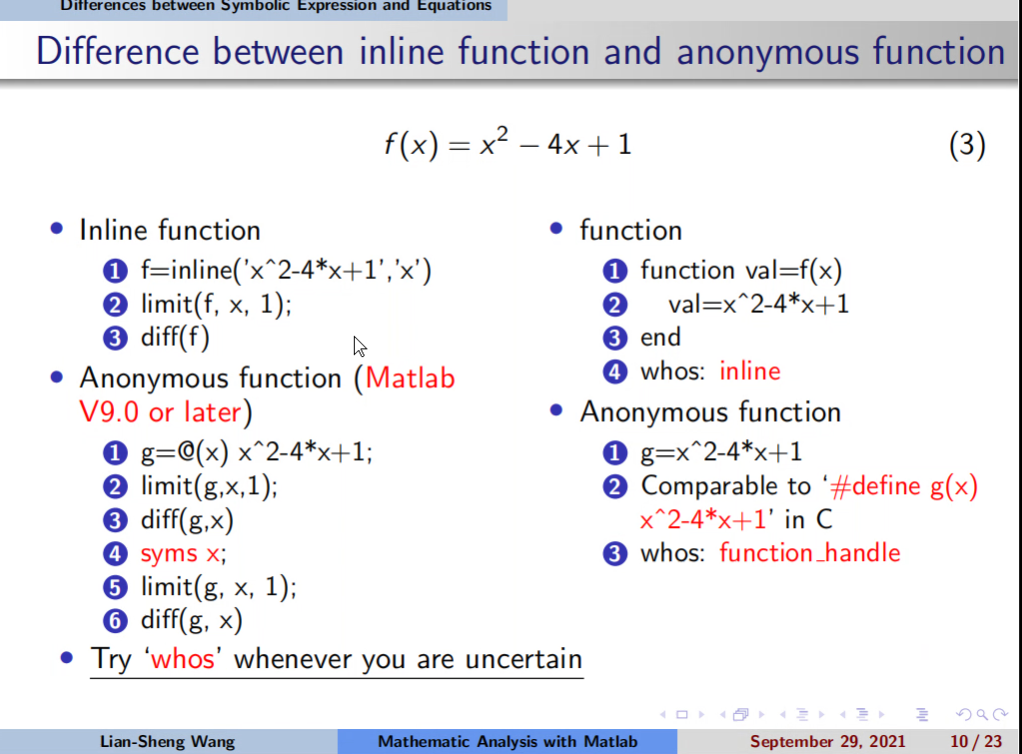

g = @(x) x^2-4*x+1;
syms x;
limit(g,x,1);
diff(g,x)

$$ans = 2\,x-4$$

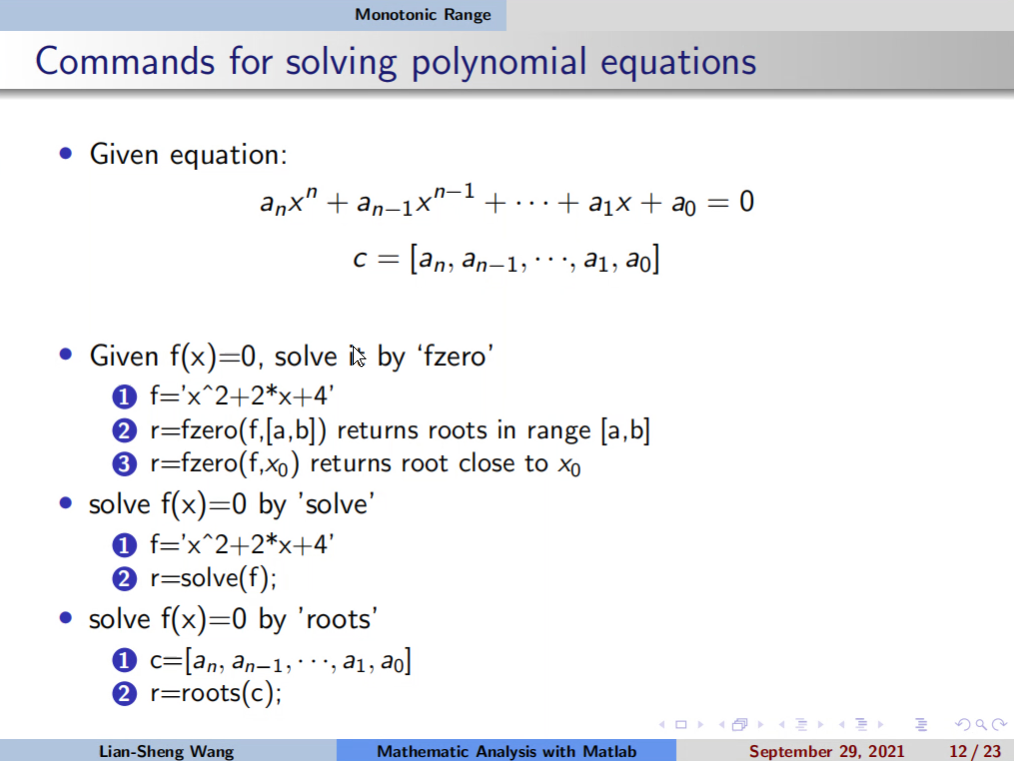

solve比fzero更强大。 root只有数值解。

syms x
f = exp(x)-6*x^2+9;
r = vpasolve(f)

$$r = -1.2441979967238808493912781618914$$


f = x.^3 + 6.*x.^2 + 29;
r = double(solve(f))

r =    0.3274 - 2.0617i
   0.3274 + 2.0617i
  -6.6548 + 0.0000i


r = roots([1,6,0,29])

r =   -6.6548 + 0.0000i
   0.3274 + 2.0617i
   0.3274 - 2.0617i


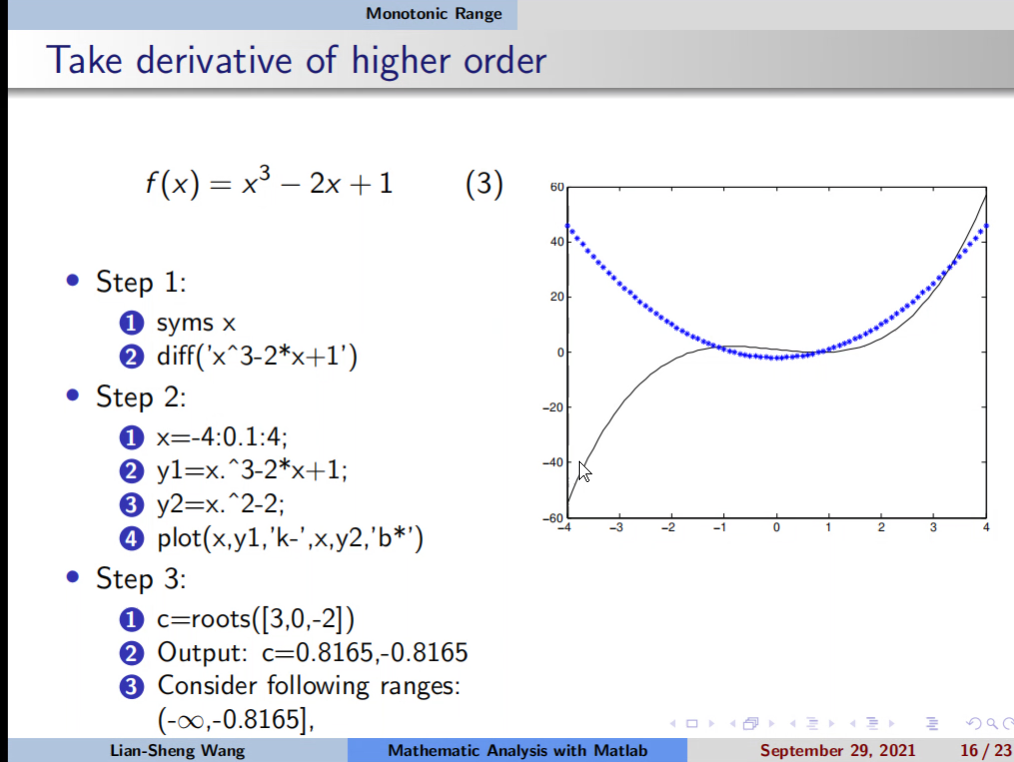

Practice: